# 3-D Interpolation Using Full Grid vs. Grid Vectors

Interpolate 3-D data using two methods to specify the query points.

Create and plot a 3-D data set representing the function $z\left(x,y\right)=\frac{\sin \left(x^2 +y^2 \right)}{x^2 +y^2 }$ evaluated at a set of gridded sample points in the range [-5,5].

[x,y] = ndgrid(-5:0.8:5);
z = sin(x.^2 + y.^2) ./ (x.^2 + y.^2);
surf(x,y,z)

Create a gridded interpolant object for the data.

F = griddedInterpolant(x,y,z);

Use a finer mesh to query the interpolant and improve the resolution.

[xq,yq] = ndgrid(-5:0.1:5);
vq = F(xq,yq);
surf(xq,yq,vq)

In cases where there are a lot of sample points or query points, and where memory usage becomes a concern, you can use *grid vectors* to improve memory usage.

- When you specify grid vectors instead of using `ndgrid` to create the full grid, `griddedInterpolant` avoids forming the full query grid to carry out the calculations.

- When you pass grid vectors, they are normally grouped together as cells in a cell array, `{xg1, xg2, ..., xgn}`. The grid vectors are a compact way to represent the points of the full grid.

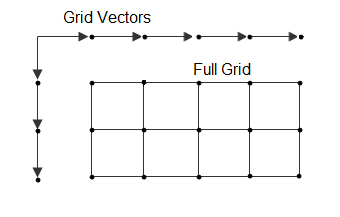

Alternatively, execute the previous commands using grid vectors.

x = -5:0.8:5;
y = x';
z = sin(x.^2 + y.^2) ./ (x.^2 + y.^2);
F = griddedInterpolant({x,y},z);
xq = -5:0.1:5;
yq = xq';
vq = F({xq,yq});
surf(xq,yq,vq)

*Copyright 2012 The MathWorks, Inc.*